# Show color gamut of OL490

## Draw

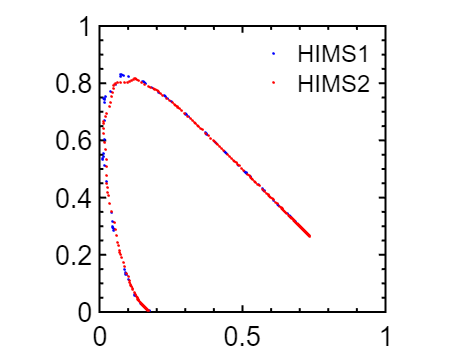

data1 = ol490_gamut('col_spec_HIMS1_07032022.mat');
data2 = ol490_gamut('col_spec_HIMS2_07032022.mat');

clf
hold on
plot(data1(:,1),data1(:,2),'b.');
plot(data2(:,1),data2(:,2),'r.');
legend('HIMS1','HIMS2')
axis([0 1 0 1])
axis square

hfig = gcf;
haxis = get(hfig,'CurrentAxes');
PlotBeautify(haxis)


save('ol490_gamut','data1','data2')

function data = ol490_gamut (fn)

#### Obtain measurement data

%load col_spec_HIMS1_07032022.mat
%load col_spec_HIMS2_07032022.mat

load(fn)

cc = ColorConversionClass;
speC_d65 = CIE_D.getSpectrum(6500);
spec_d65 = speC_d65.amplitude';

% visual
if 0
    clf
    hold on
    for i = 1:1024
        ref = col_spec(i,:);
        spd = spec_d65 .* ref;
        plot(380:780,spd)
    end
end

#### Calculate CIE xy

Following `RGB_in_xyY.m`

data = zeros(1024,2);
for i = 1:1024
    ref = col_spec(i,:);
    spd = spec_d65 .* ref;
    spd = spd(1:10:401)';
    XYZ = cc.spd2XYZ(spd);
    xyz = XYZ ./ sum(XYZ);
    data(i,:) = xyz(1:2);
end

end